# Signaler och system - Laboration 1

**Uppgift 1b: **Beräkna de tidsdiskreta värdena y[n] för differensekvationen

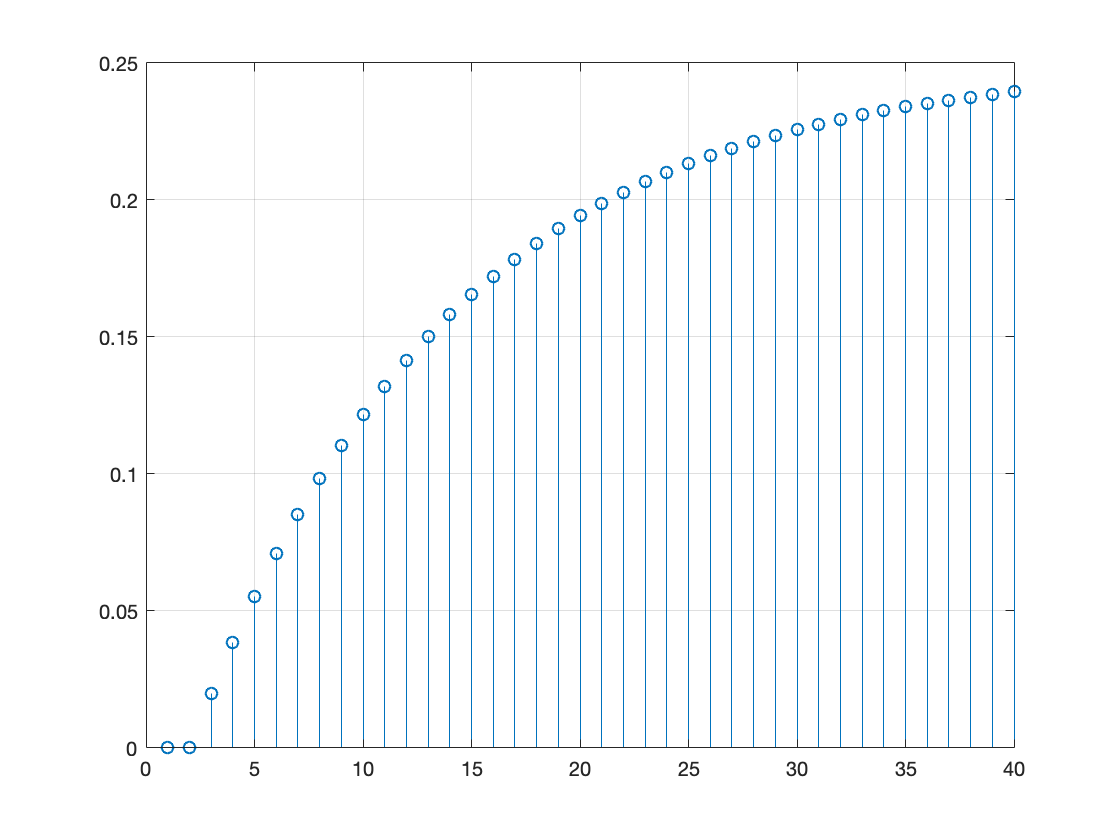

%Beräkna antal steg i index n
N=0.8/0.02;

%Skapa stegfunktion
u=[0 ones(1,N-1)];

%Exekvera differensekv (m börjar på 2 => n=0)
y(1)=0;

for m=2:N
    y(m)=0.92*y(m-1)+0.02*u(m-1);
end

%Rita resultatet
figure(1); stem(y); grid; xlim([0 40]);

**Uppgift 3:**

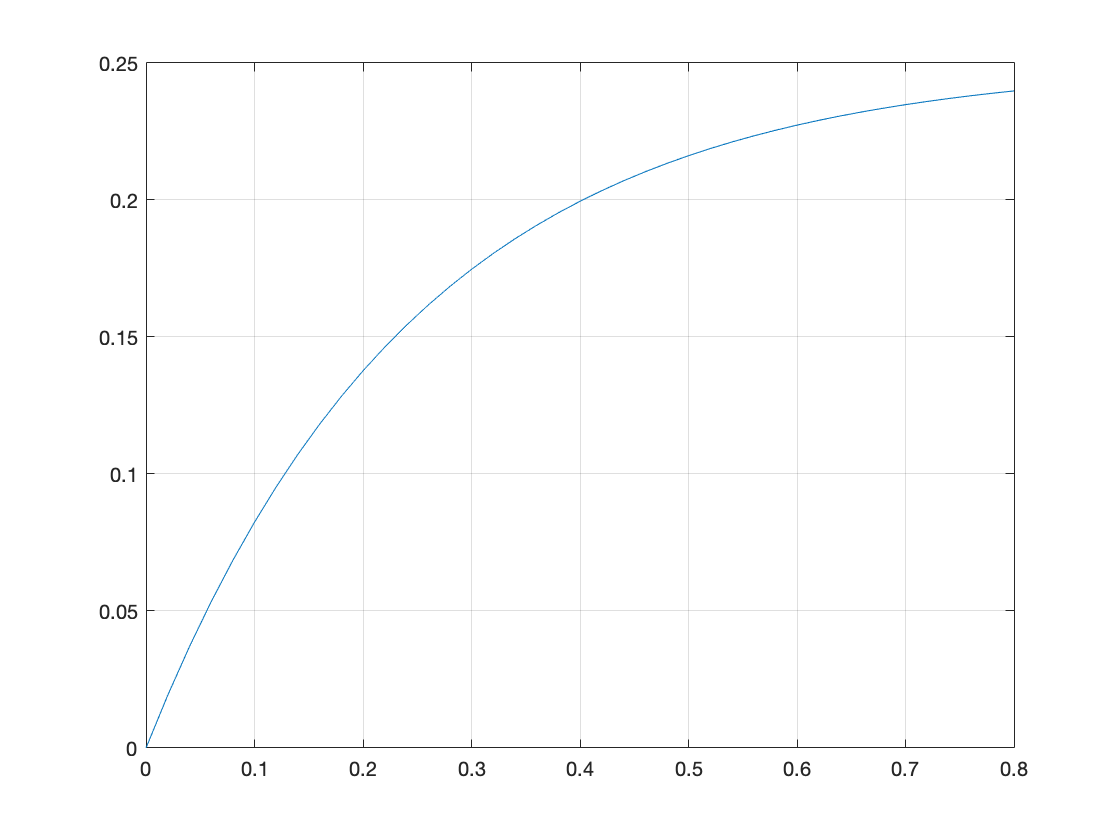

t=0:0.02:0.8;

y=1/4*(1-exp(-4*t));

figure(2); plot(t,y); grid;

**Uppgift 4:**

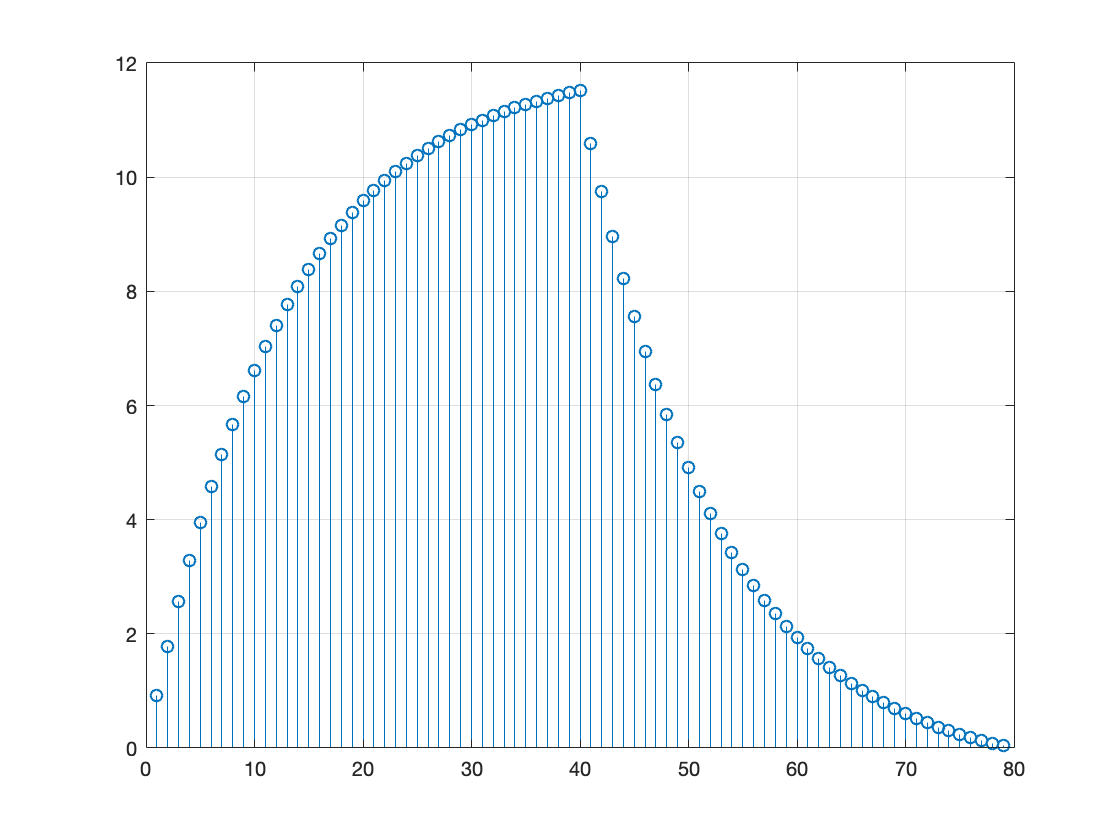

clear all;
u=[ones(1,40)];

T = 0.02;
n = 1:40;
h = exp(-4*n*T); % Impulssvar

y=conv(u,h);
figure(3); stem(y); grid;

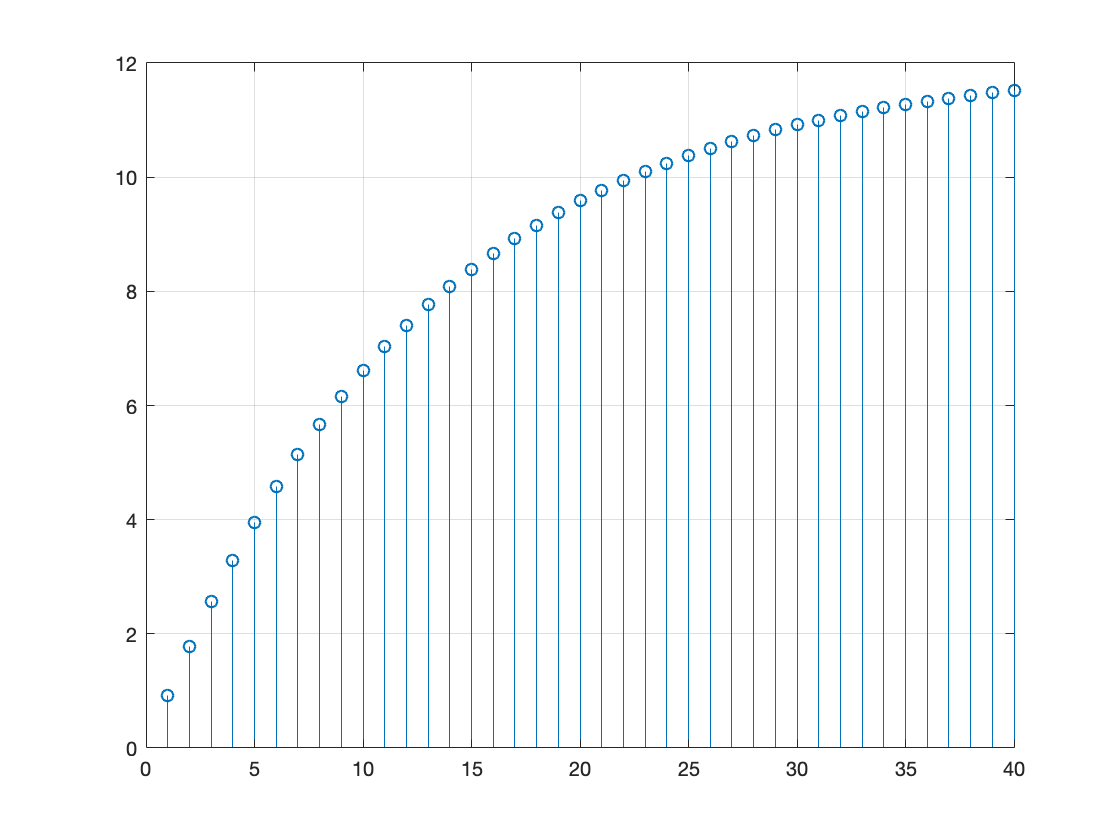


y=y(1:40);
figure(4); stem(y); grid;

**Uppgift 5:**

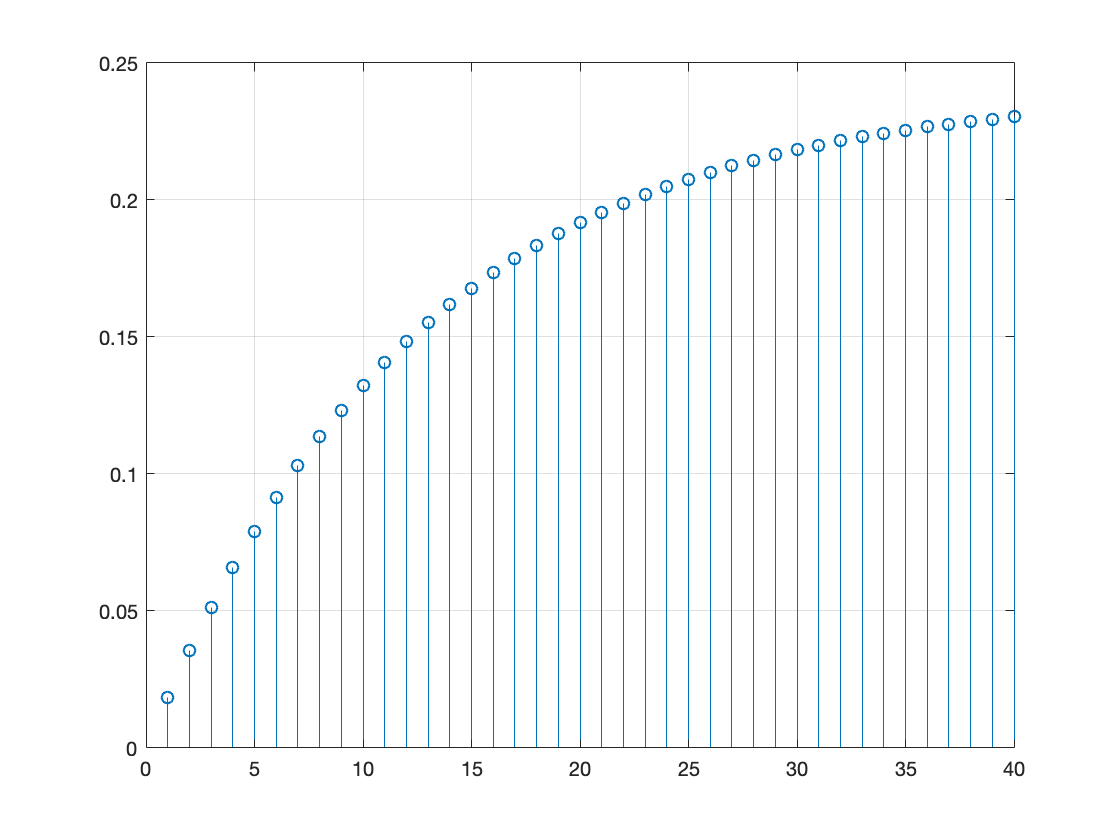

z=y*T;
figure(5); stem(z); grid;

**Uppgift 6:**

clear all
[y,fs]=audioread('Trubadur.wav');
N_1=fix(fs*0.3)

N_1 = 3307

h=[1 zeros(1,N_1) 1 zeros(1,N_1) 1];
z=conv(h,y);
%soundsc(z,fs);

**Uppgift 7:**

clear all

load('piano1.mat'); 

%%fs = 22050; 
%%fs = 5512.5;

%%soundsc(y1,fs); 

**Uppgift 8:**

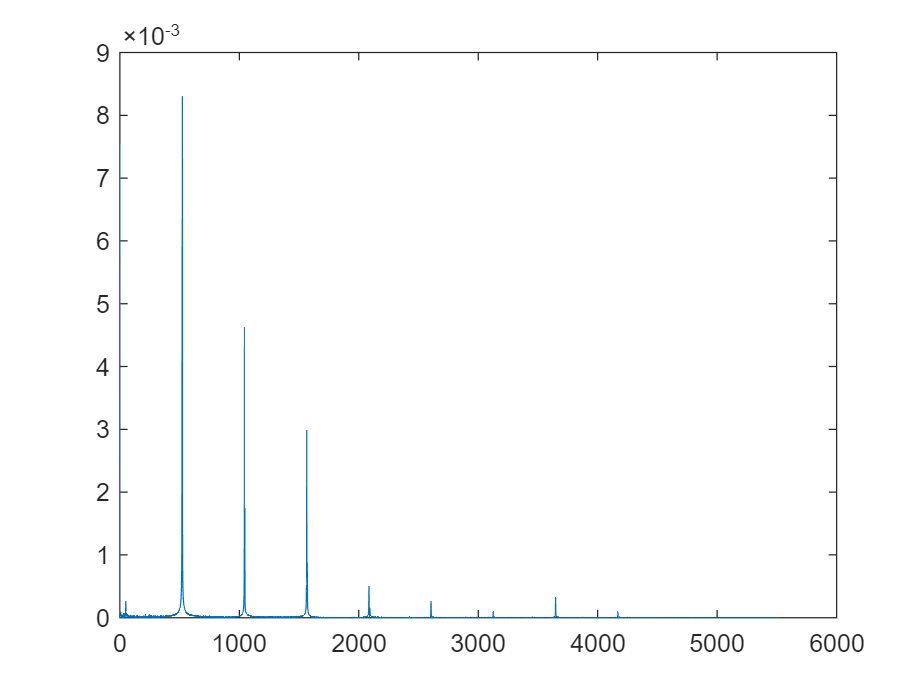

Y = fft(y1);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


deltaF = fs/N;

deltaF = 1.1024

**Uppgift 10:**

clear all;

load radar.mat;

f_0=3.65*10^9 %Hz

f_0 = 3.6500e+09

c=3.00*10^8 %m/s

c = 300000000

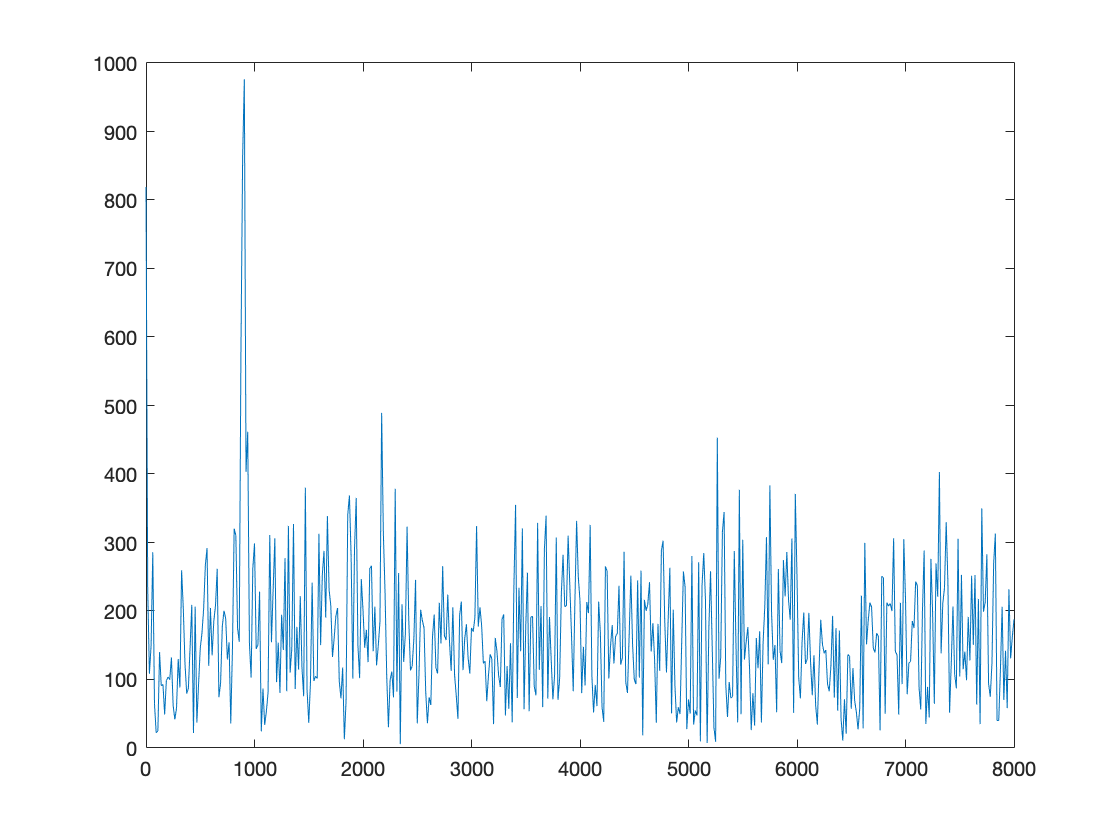


Y = fft(y);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


f_mott=906;

%f_mott = (2*v*f_0)/c;
v = (f_mott * c) / (2*f_0);
v %37 km/h

v = 37.2329


%v=
%f_mott=(2*v*f_0)/c;

**Uppgift 11:**

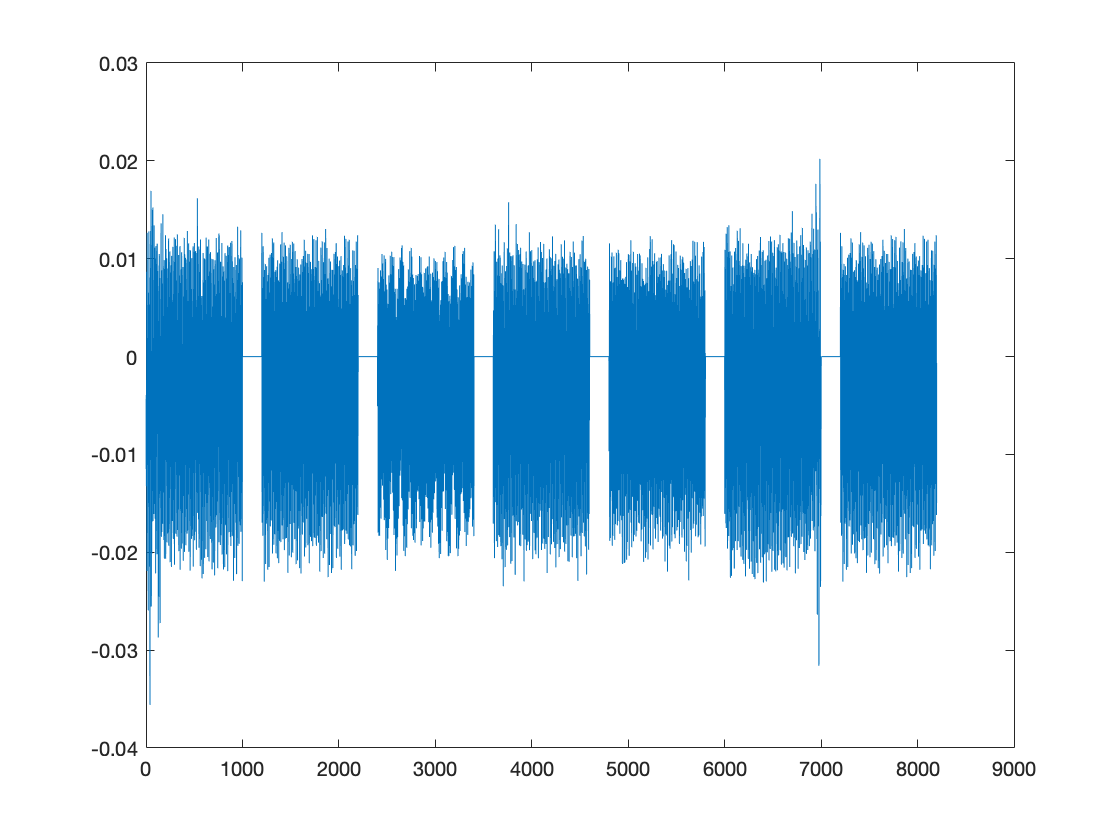

clear all;

load phonenumber.mat;

plot(y);

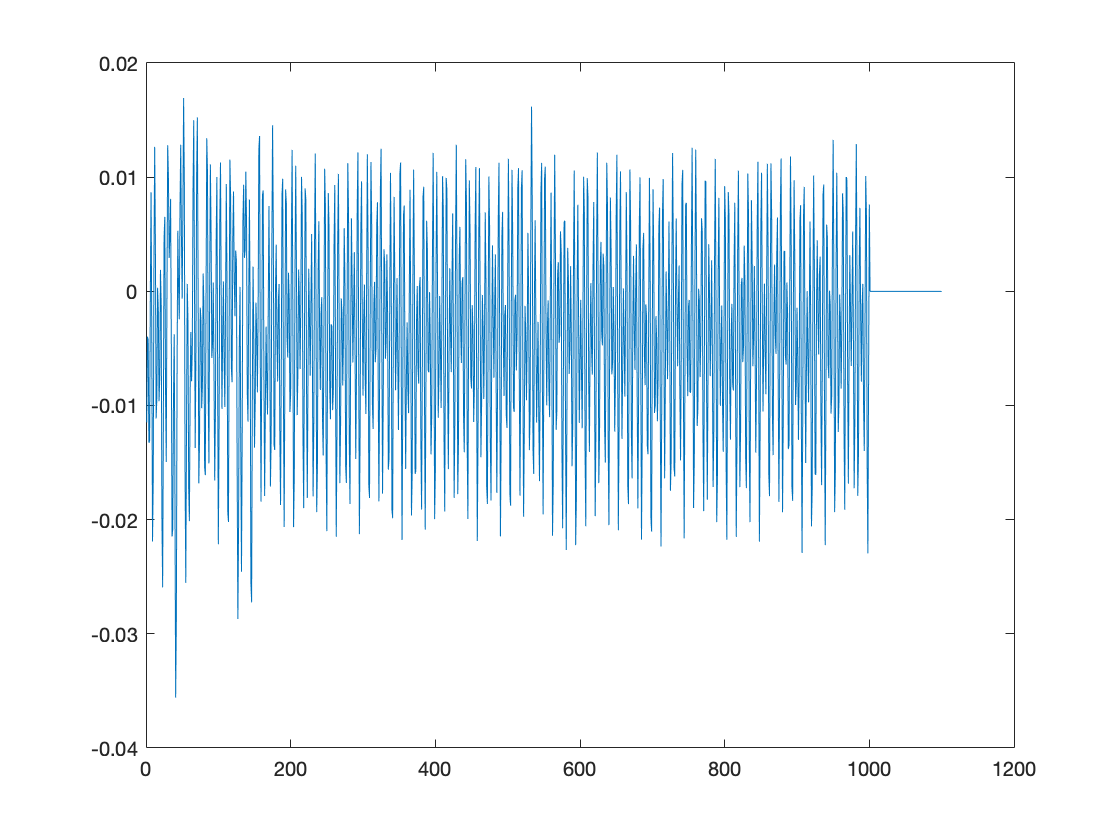


y1 = y(1,1:1100); %nr7
plot(y1);

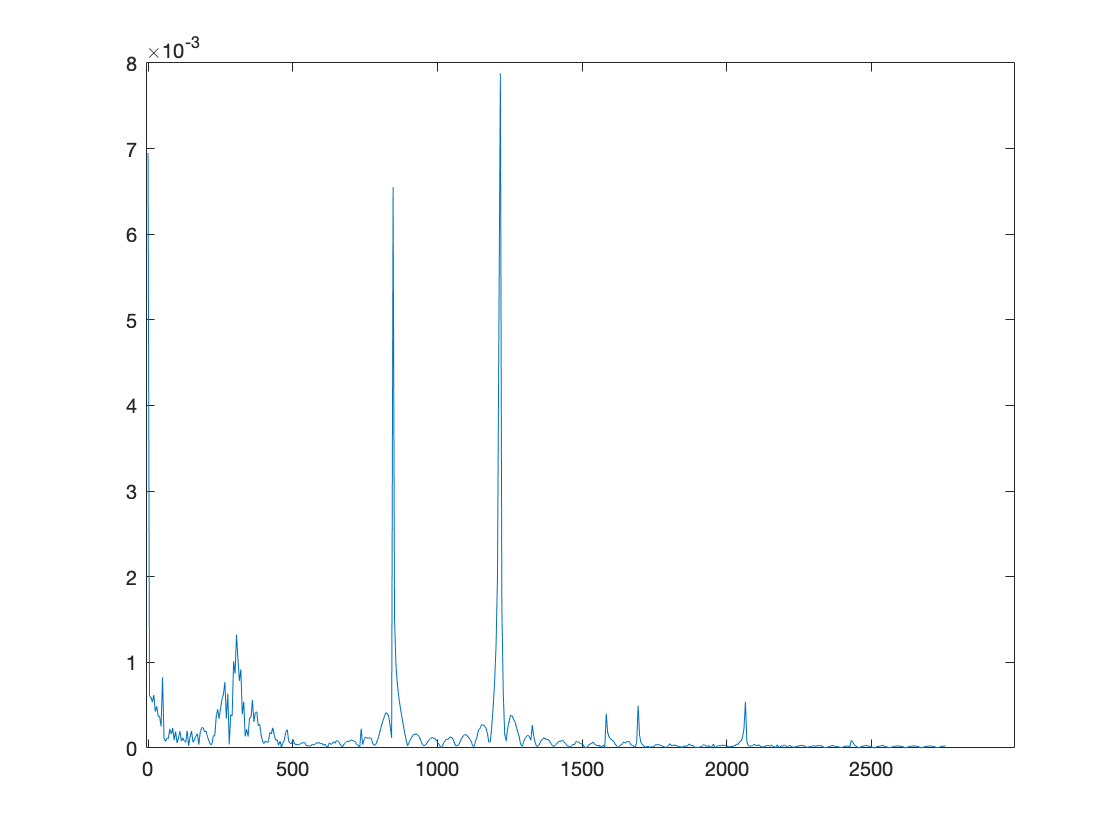


Y = fft(y1);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


y2 = y(1,1100:2300); %nr4
plot(y1);

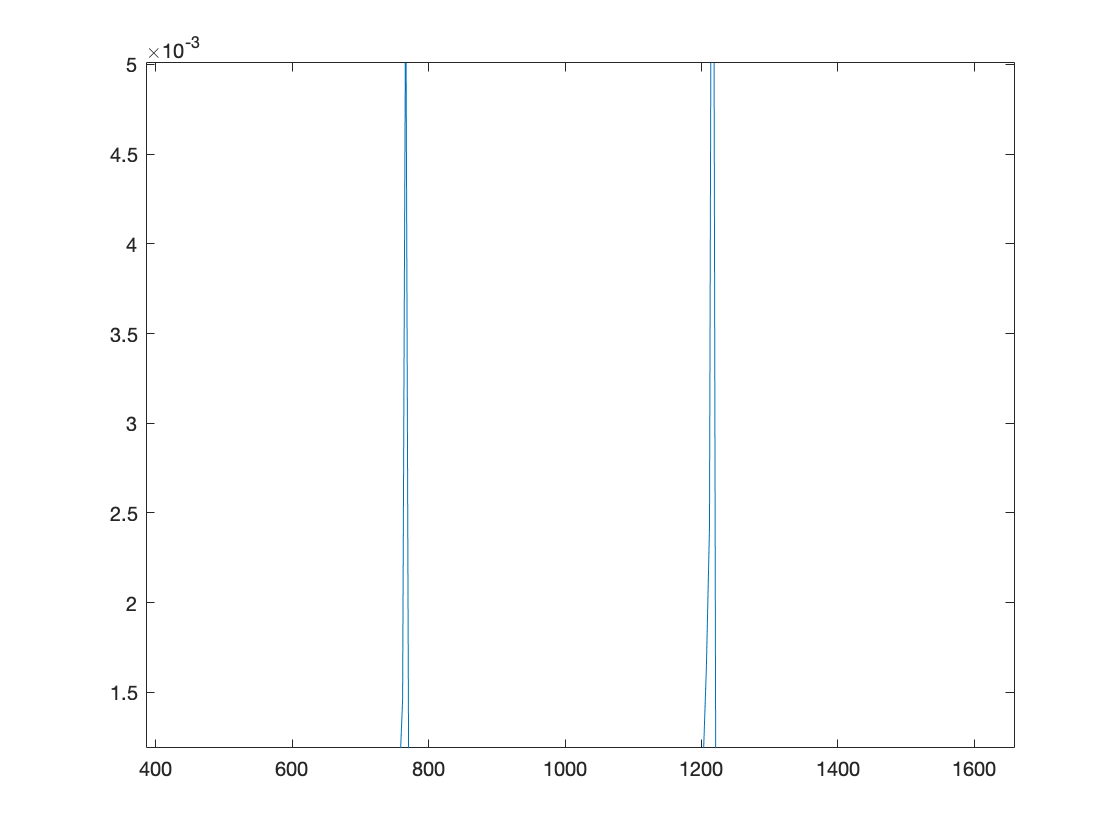


Y = fft(y2);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


y3 = y(1,2300:3500); %nr6
plot(y1);

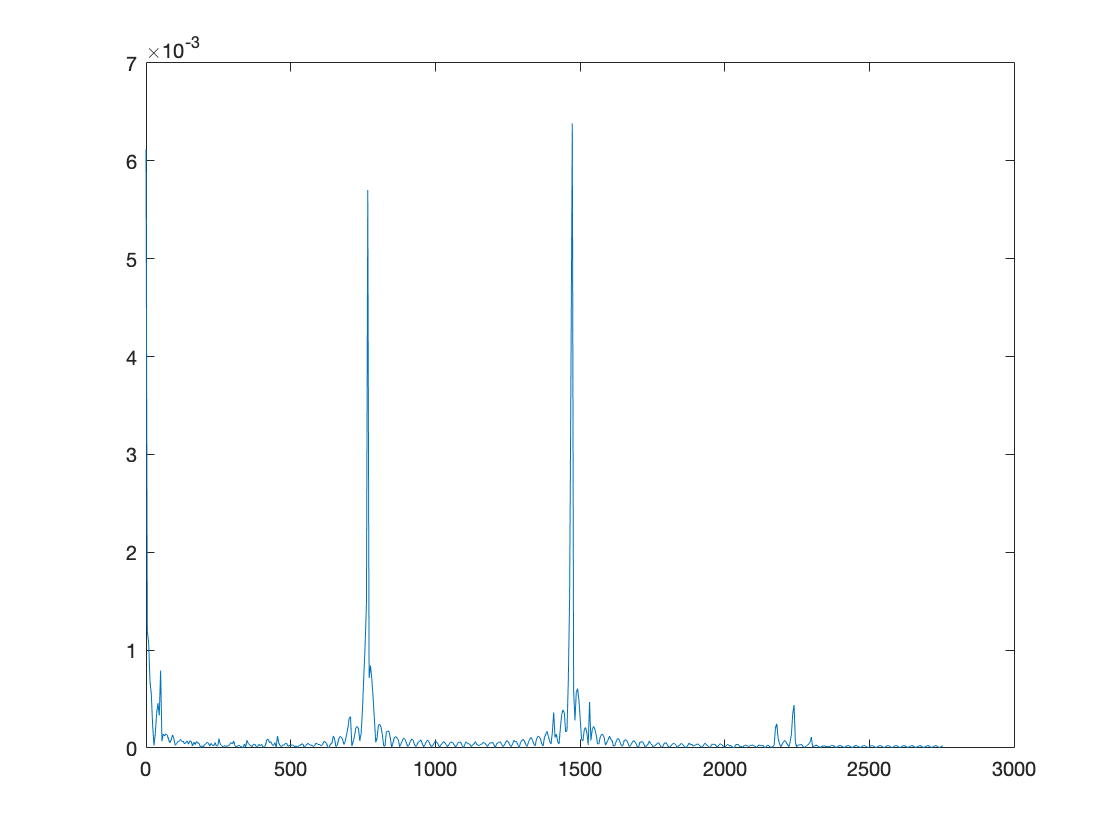


Y = fft(y3);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


y4 = y(1,3500:4700); %nr8
plot(y1);

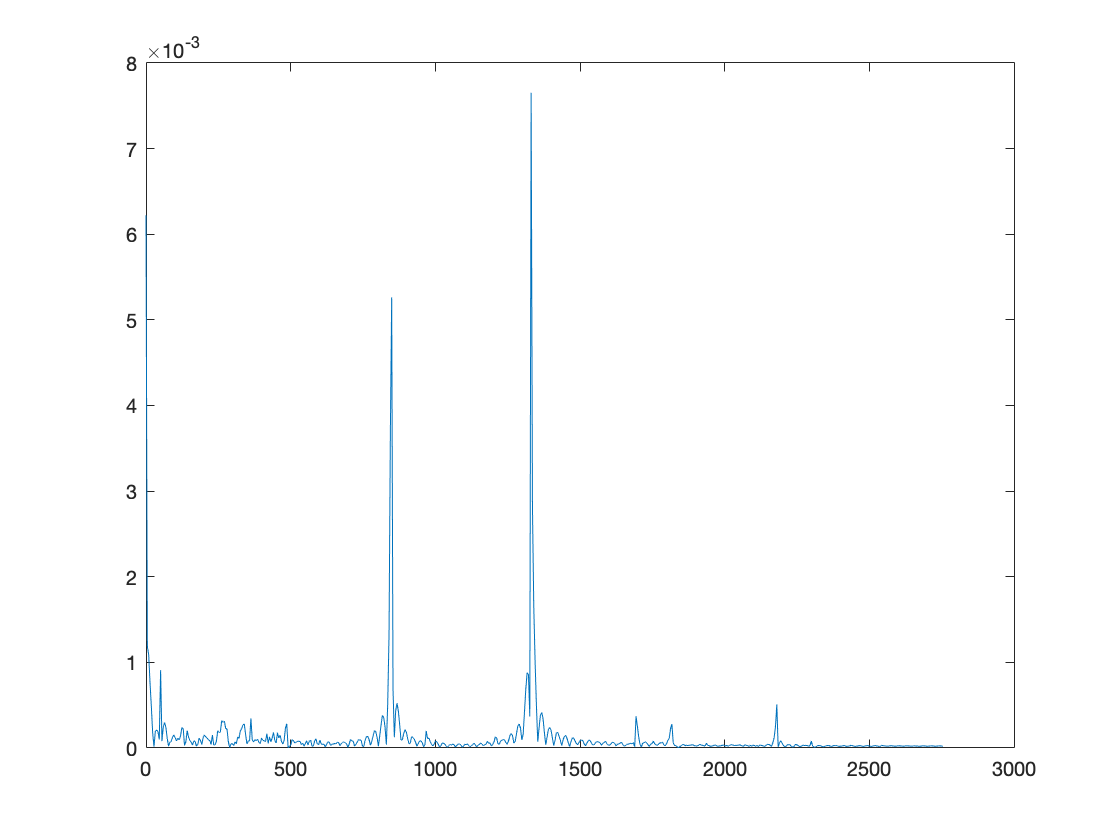


Y = fft(y4);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


y5 = y(1,4700:5900); %nr9
plot(y1);

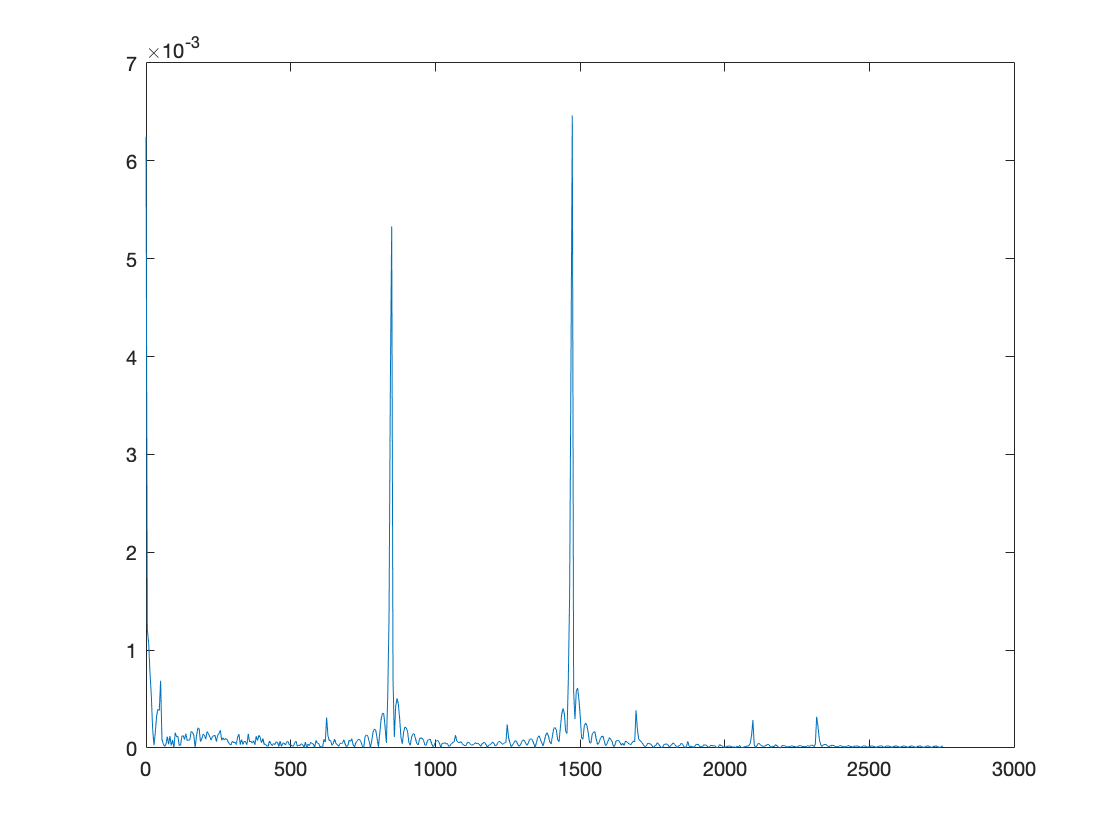


Y = fft(y5);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


y6 = y(1,5900:7100); %nr0
plot(y1);

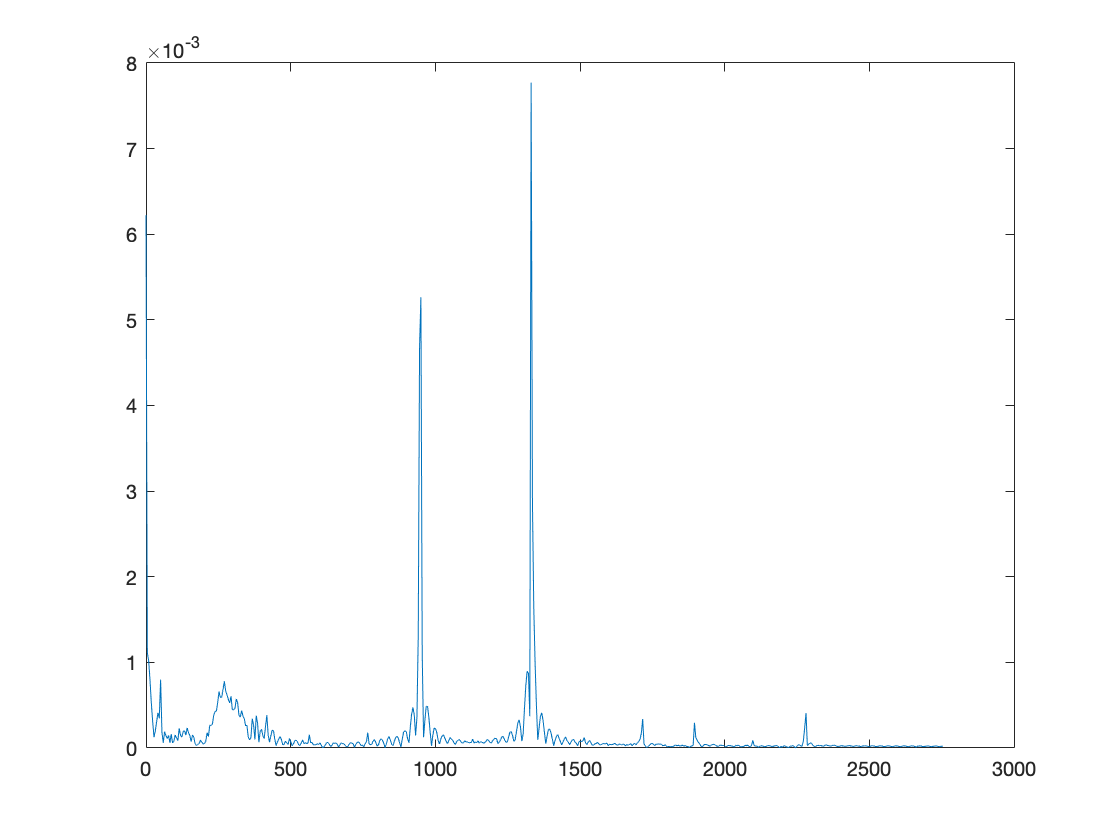


Y = fft(y6);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));


y7 = y(1,7100:8100); %nr4
plot(y1);

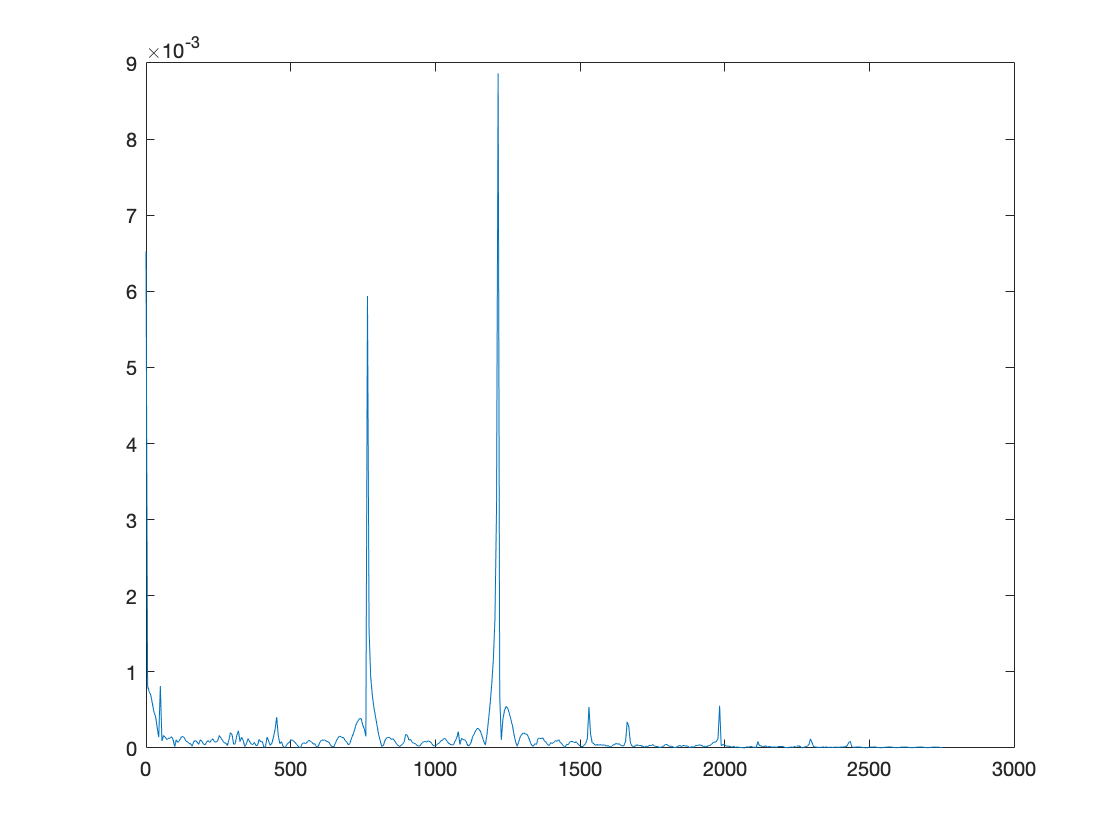


Y = fft(y7);
N = length(Y);
f = 0:fs/N:fs/2;
X_magn = abs(Y)/(N/2);
plot(f, X_magn(1:length(f)));